# Universal Approximation Theorem

## Log-sigmoid

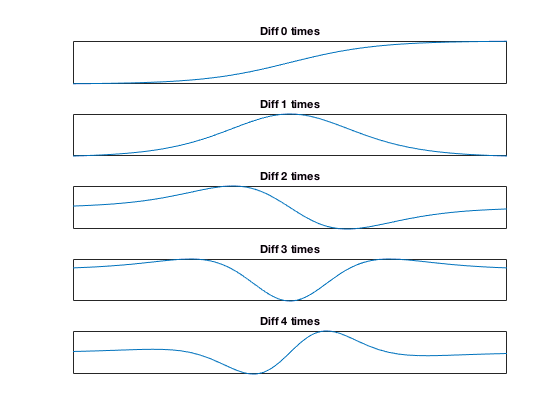

syms('x');
f(x) = logsig(x);

n = 5;
for i = 1:n
    subplot(n, 1, i);
    fplot(diff(f, x, i-1));
    title(sprintf('Diff %d times', i-1));
    set(gca, 'XTick', [], 'YTick', []);
end

## Inverse log-sigmoid

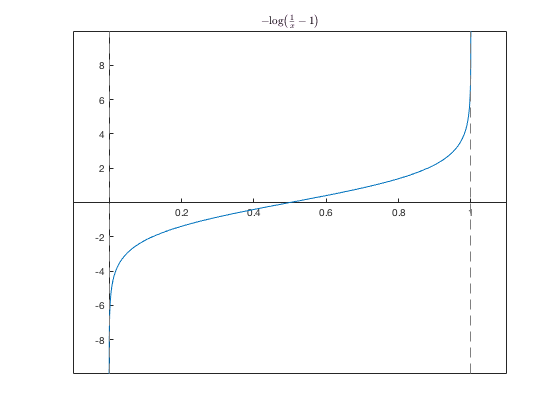

syms('x');
f(x) = logsig(x);
g(x) = finverse(f(x));
figure;
fplot(g(x), [-0.1, 1.1]);
ylim([-10, 10]);
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
title(['$', latex(g), '$'], 'Interpreter', 'latex');

disp(g(x));

$$-\log\left(\frac{1}{x}-1\right)$$

## Hyperbolic tangent sigmoid

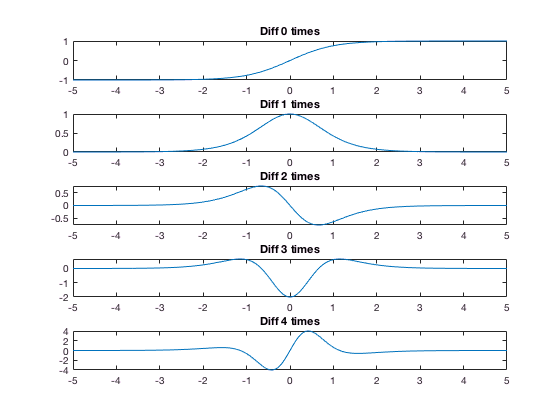

syms('x');
f(x) = 2 * logsig(2 * x) - 1;

h_fig = figure('Name', 'Log-Sigmoid', 'NumberTitle', 'off');
n = 5;
for i = 1:n
    subplot(n, 1, i);
    fplot(diff(f, x, i-1));
    title(sprintf('Diff %d times', i-1));
    %set(gca, 'XTick', [], 'YTick', []);
end

disp(f(x))

$$\frac{2}{{\mathrm{e}}^{-2\,x}+1}-1$$

## Hyperbolic tangent vs. Log-sigmoid

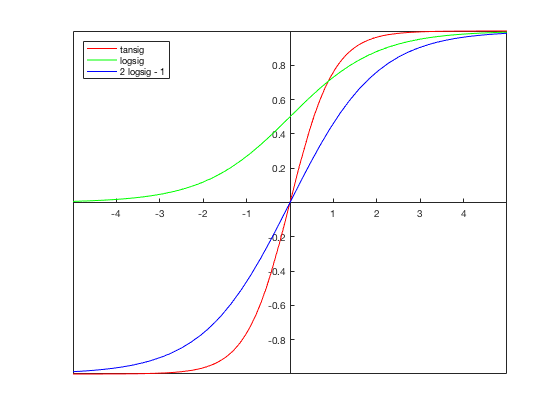

syms('x');
figure();
fplot(tanh(x), 'Color', 'red')
hold('on');
fplot(logsig(x), 'Color', 'green')
fplot(2 * logsig(x) - 1, 'Color', 'blue')
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
legend('tansig', 'logsig', '2 logsig - 1', 'Location', 'northwest')
hold('off');

## Perceptron

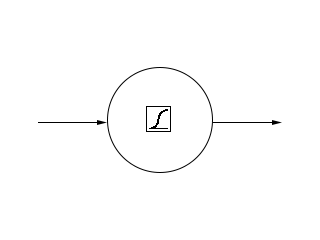

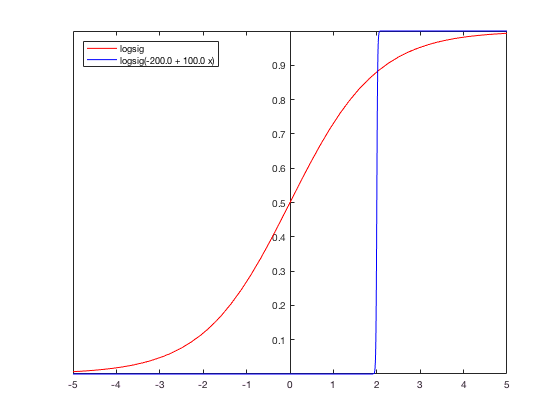

syms('x', 'w0', 'w1');
f(w0, w1, x) = logsig(w0 + w1 * x);
figure();
fplot(logsig(x), 'Color', 'red');
hold('on');
w0 = -200;
w1 = 100;
fplot(f(w0, w1, x), 'Color', 'blue');
hold('off');
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
legend('logsig', sprintf('logsig(%.1f + %.1f x)' ,w0, w1), 'Location', 'NorthWest');

## Sum of two linear functions

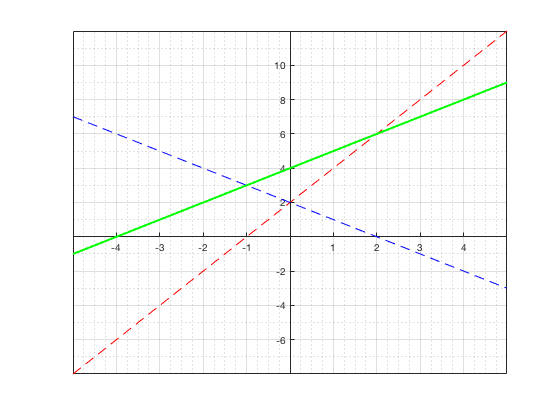

syms('x');
w11 = [2, 2];
w12 = [-1, 2];
w21 = [1, 1, 0];

l11(x) = w11 * [x; 1];
l12(x) = w12 * [x; 1];
l21(x) = w21 * [l11(x); l12(x); 1];

figure;
fplot(l11(x), 'Color', 'red', 'LineStyle', '--');
grid('on');
grid('minor');
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');

hold('on');
fplot(l12(x), 'Color', 'blue', 'LineStyle', '--');
fplot(l21(x), 'Color', 'green', 'LineWidth', 2);
hold('off');

## Heaviside step function

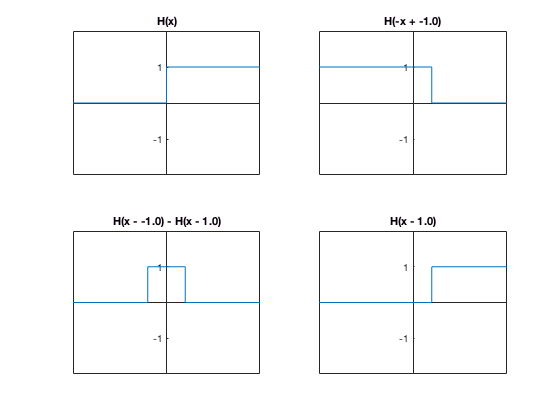

syms('x');
a = -1;
b = 1;
ylimits = [-2, 2];

figure;

% heaviside
subplot(2, 2, 1);
fplot(heaviside(x));
ylim(ylimits);
title('H(x)');
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');

% hevised(-x + a)
subplot(2, 2, 2);
fplot(heaviside(-(x - b)))
ylim(ylimits);
title(sprintf('H(-x + %.1f)', a));
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');

% hevised(x - a) - heaviside(x - b)
subplot(2, 2, 3);
fplot(heaviside(x - a) - heaviside(x - b))
ylim(ylimits);
title(sprintf('H(x - %.1f) - H(x - %.1f)', a, b));
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');

% hevised(x - b)
subplot(2, 2, 4);
fplot(heaviside(x - b))
ylim(ylimits);
title(sprintf('H(x - %.1f)', b));
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');

## Piecewise function

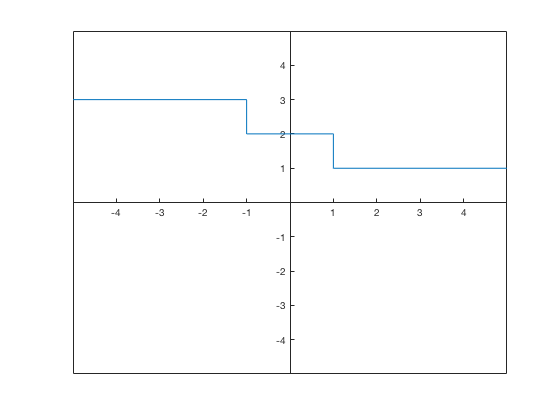

syms('x');
a = -1;
b = 1;
figure;
f(x) = ...
    3 * heaviside(-x + a) + ...
    2 * (heaviside(x - a) - heaviside(x - b)) + ...
    1 * heaviside(x - b);
fplot(f(x));
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
ylim([-5, 5]);

## Approximate with step function

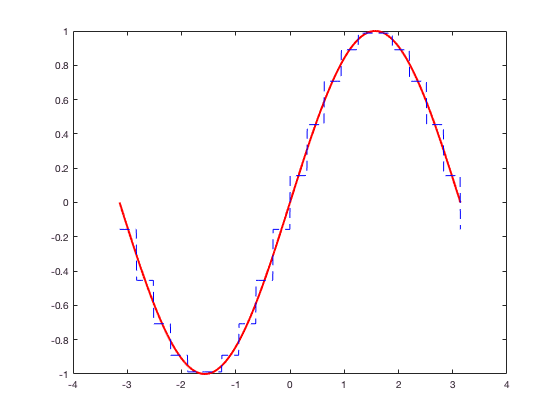

number_of_points = 1000;
number_of_intervals = 20;
f = @sin;

x = linspace(-pi, pi, number_of_points);
approximate_with_step_function1(f, x, number_of_intervals);

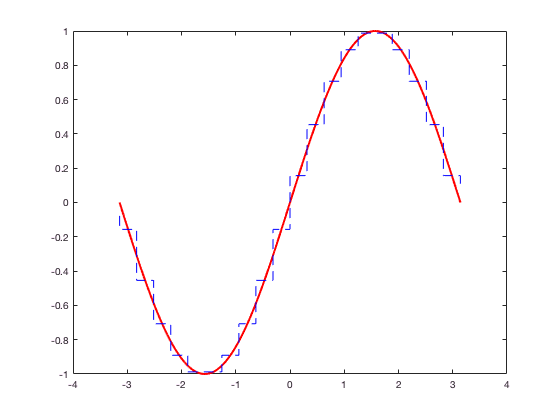

syms('t');

min_x = min(x(:));
max_x = max(x(:));

s = linspace(min_x, max_x, number_of_intervals + 1);

g(t) = sym(0);
for i = 1:number_of_intervals
    g(t) = g(t) + f((s(i) + s(i+1)) / 2) * (heaviside(t - s(i)) - heaviside(t - s(i+1)));
end

% g(t) = symsum( ...
%     f((s(i) + s(i+1)) / 2) * (heaviside(t - s(i)) - heaviside(t - s(i+1))), ...
%     i, 1, number_of_intervals);

figure;
plot(x, f(x), 'Color', 'red', 'LineStyle', '-', 'LineWidth', 2);
hold('on');
fplot(g(t), [min_x, max_x], 'Color', 'blue', 'LineStyle', '--');
hold('off');     s

## 3D log-sigmoid

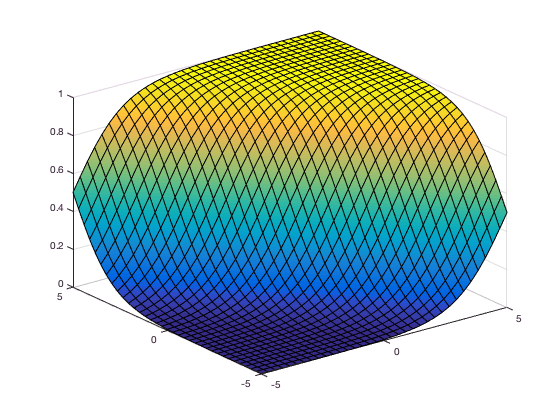

syms x1 x2
w0 = 0;
w1 = 1;
w2 = 1;

fsurf(gca, logsig(w0 + w1 * x1 + w2 * x2));

## 3D step-function

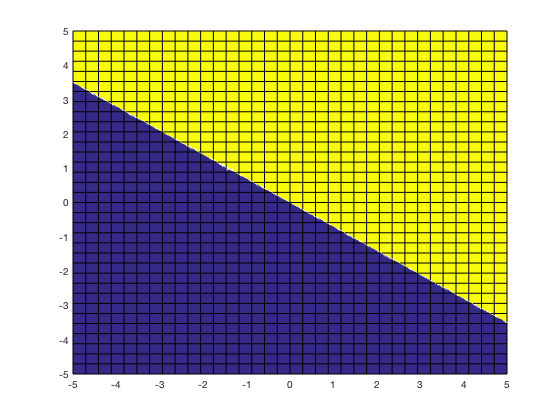

syms x y sx sy

step(x, y, sx, sy) = heaviside((x - sx) + (y - sy));

figure;
% fsurf(step(x, y, 0, 1));
fsurf(heaviside(0.7 * x +  1 * y));
view([0, 90])

## 3D bump

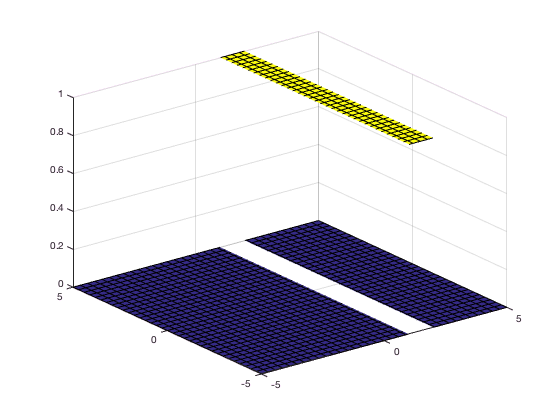

syms x x1 x2

bump(x, x1, x2) = heaviside(x - x1) - heaviside(x - x2);

x1 = 1;
x2 = 2;

fsurf(gca, bump(x, x1, x2));

## 3D rotated bump

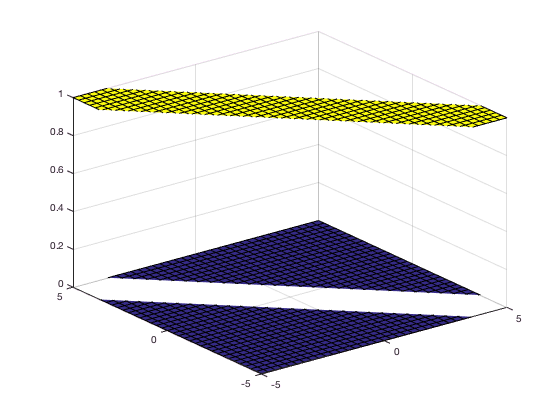

syms x x1 x2 t


bump(x, x1, x2, t) = heaviside(cos(t) * x + sin(t) * y - x1) - heaviside(cos(t) * x + sin(t) * y - x2);

x1 = -1;
x2 = 1;
t = pi / 4;

fsurf(gca, bump(x, x1, x2, t));

## 3D tower

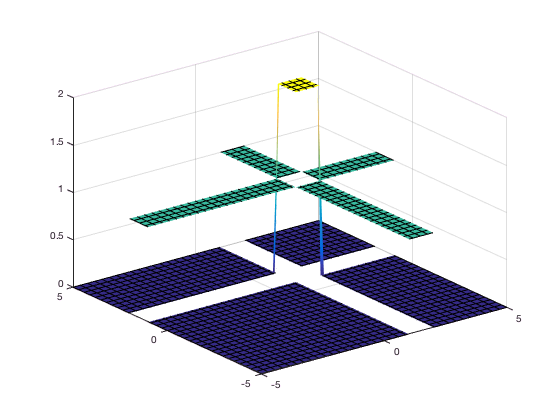

syms x y x1 x2 y1 y2

bump(x, x1, x2) = heaviside(x - x1) - heaviside(x - x2);
tower(x, y, x1, x2, y1, y2) = bump(x, x1, x2) + bump(y, y1, y2);

x1 = 1;
x2 = 2;

y1 = 1;
y2 = 2;

figure;
fsurf(gca, tower(x, y, x1, x2, y1, y2));

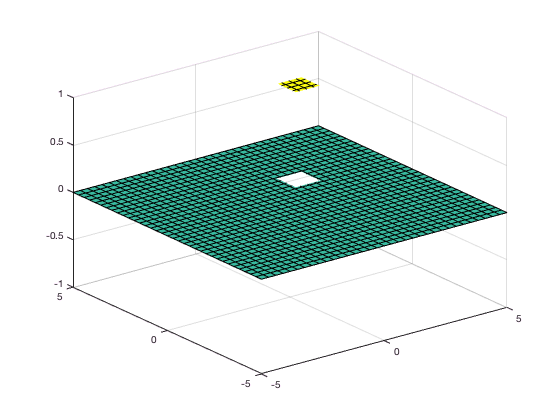


figure;
fsurf(gca, heaviside(tower(x, y, x1, x2, y1, y2) - 1.5));

## 3D tower (rotation method for one hidden layer NN)

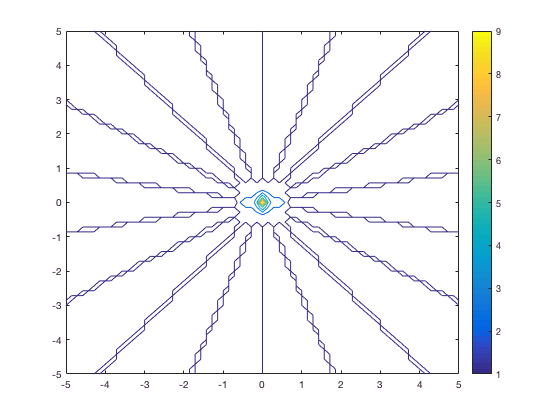

syms x y b t

bump(x, y, b, t) = heaviside((cos(t) * x + sin(t) * y) + b) - heaviside((cos(t) * x + sin(t) * y) - b);

tower(x, y, b) = sym(0);

for t = 0:20:179
    tower(x, y, b) = tower(x, y, b) + bump(x, y, b, deg2rad(t));
end

b = 0.1;
fcontour(tower(x, y, b));
colorbar;